# **Compute cone mosaic excitations to an ISETBio scene.**

*This tutorial generates an ISETBio scene representing a Gabor stimulus as realized on a particular display.  It then passes the scene through the human optics (wavefront-defined), and computes cone mosaic excitations.*

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

- t_conePhotocurrentsFromSceneOnDisplay.mlx (photocurrent computation + fixational eye movements)

- `t_treeShrewConeIsomerizationsFromSceneOnDisplay.mlx ` (parameters specific to treeshrew visual system)

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Create a presentation display and a low-frequency Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

%% Create presentation display and place it 57 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

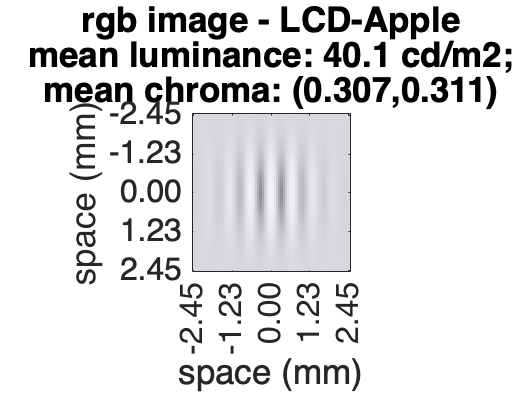

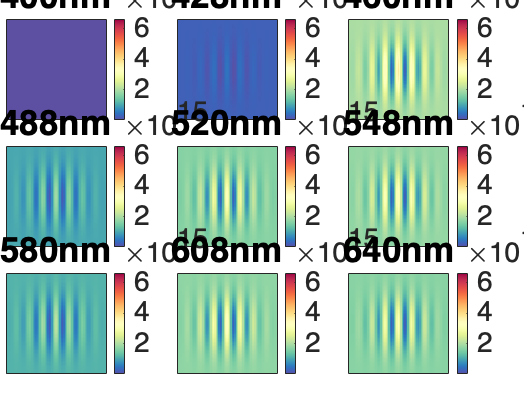

%% parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 15, ... % 15 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 0, ...                    % spatial phase in degrees
    'sizeDegs', 0.5, ...                    % 0.5 x 0.5 degrees
    'sigmaDegs', 0.3/3, ...                 % sigma of Gaussian envelope, in degrees
    'contrast', 0.9,...                     % 0.9 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );

% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 5);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene);

# **Step 2.** Compute the optical image using wavefront-aberration based optics

We employ the default human optics model which is based on average Zernike coefficiencts from 200 human subjects. The scene is passed through the optics model to compute the retinal image.

### Step 2.1 Generate the default human optics model and visualize the PSF/OTF

We are visualizing the PSF and the OTF at the in-focus wavelength (550nm), a short-wavelength (450nm), and a long-wavelength (650nm)

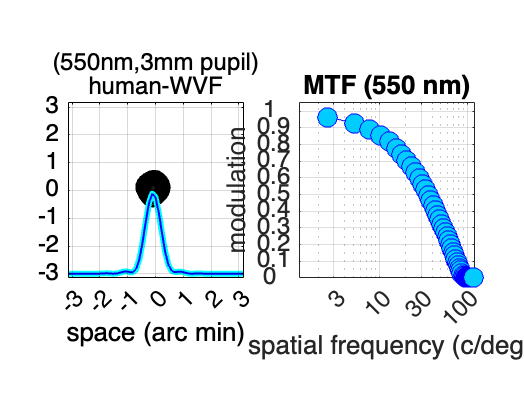

%% Generate wavefront-aberration derived human optics


theOI = oiCreate('wvf human');

% Visualize the PSFs and OTFs
visualizedSpatialSupportArcMin = 6;
visualizedSpatialSfrequencyCPD = 120;

% Visualize the PSF/OTF at 550 (in-focus)
visualizeOptics(theOI, 550, visualizedSpatialSupportArcMin, visualizedSpatialSfrequencyCPD);

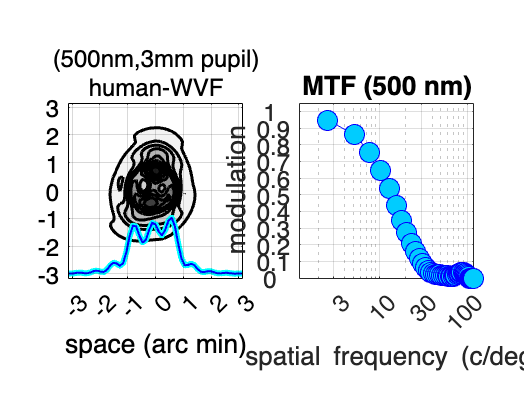

% Visualize the PSF/OTF at and at 500 nm
visualizeOptics(theOI, 500, visualizedSpatialSupportArcMin, visualizedSpatialSfrequencyCPD);

### Step 2.2 Generate the retinal optical image by passing the scene though the optics

Compute and visualize the retinal 2D image as well as 1D contrast profiles of the retinal image at different wavelengths.

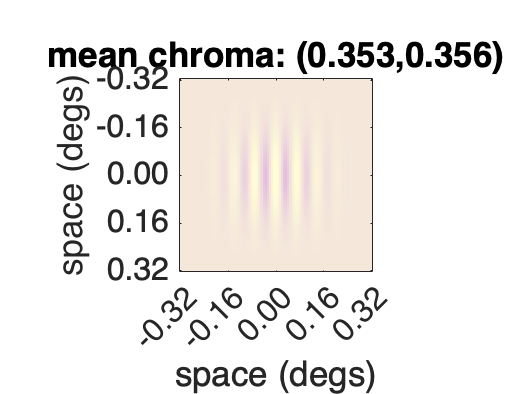

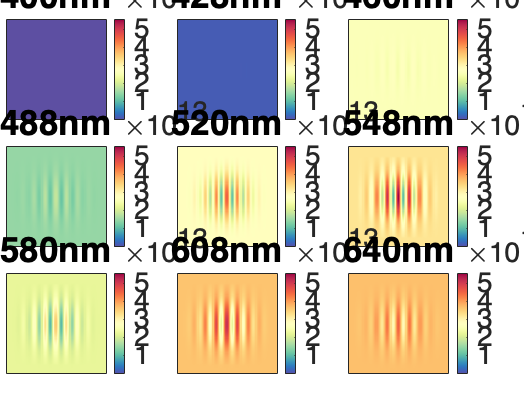

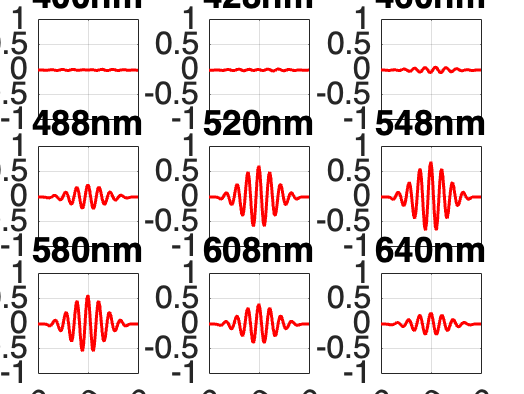

%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI, 'displayRetinalContrastProfiles', true);

Note that the chromaticity of the optical image is different from that of the scene - it is more yellowish. This is due to absorption of short wavelength light by the lens. 

# **Step 3.** Create a cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

### Step 3.1 Generate the cone mosaic

We generate a hexagonal, eccentricity-varying cone mosaic, with an integration time of 20 mseconds, and then compute its excitation response to the retinal image generated previously.

% match mosaic width to stimulus size
theMosaic = cMosaic('sizeDegs', [1, 1] * stimParams.sizeDegs, ...  % match mosaic width to stimulus size
            'integrationTime', 20 / 1000);                         % 20 msec integration time

Loading cone mosaic data from /Users/lingqiz/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/right_eye_cones_58deg_mosaic.


### Step 3.2 Compute mosaic responses to the optical image

Compute a number of response instances asumming no fixational eye movements.

nTrialsNum = 10;

% Compute mosaic excitation responses
% The first return is the noise free response (Poisson mean),
% the second return is the noisy response samples
[average, coneExcitations] = theMosaic.compute(theOI, 'nTrials', nTrialsNum);

	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.


### Step 3.3 Visualize results. 

We are visualizing the cone mosaic excitations below.

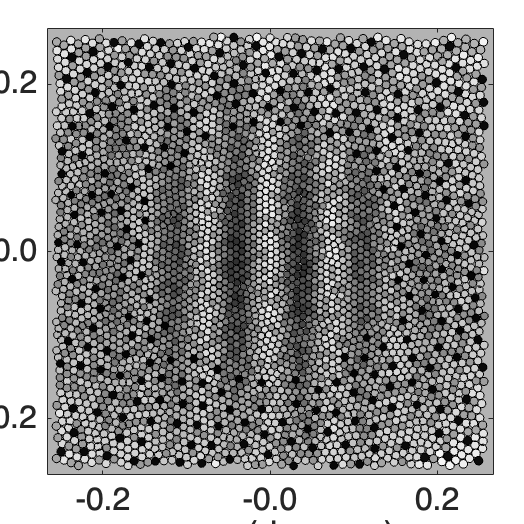

%% Visualize cone mosaic and its cone excitation responses
% Set the lower and upper limit of visualization range
activationRange = prctile(coneExcitations(:), [1 99]);
theMosaic.visualize('activation', average, ...
                    'activationRange', activationRange);